# Introduction to MATLAB

MATLAB is an extensive language designed for working with all types of data. In this document we will cover basic MATLAB operations for arrays.

## Vectors, Matrices, and Arrays

Remember some of the common terms used to describe different numeric variables. You will find these terms used in the rest of this course as well as in MATLAB documentation.

Depending on its dimensions, a variable is called as a *scalar*, a *vector*, or a *matrix*.

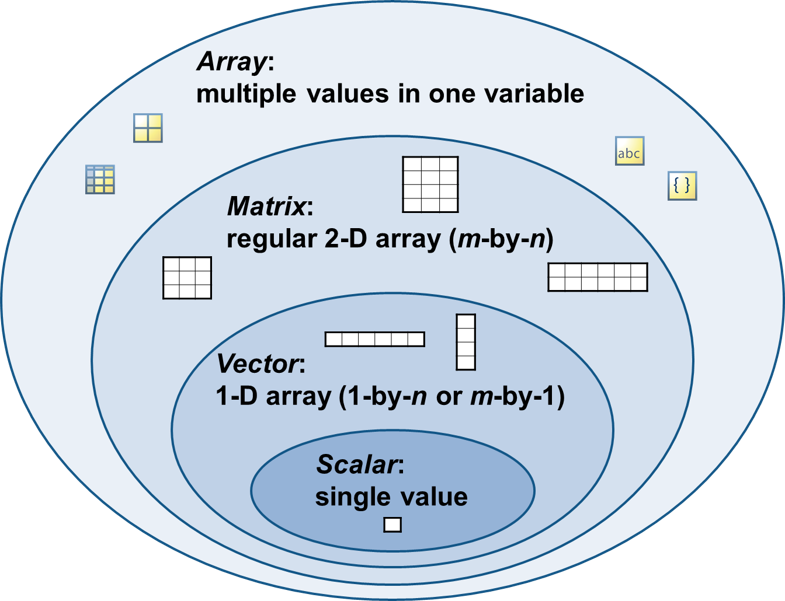

In general, a variable that contains multiple values is called an array. Scalars, vectors, and matrices are therefore types of arrays.

### Evenly-Spaced Vectors

You can use the colon operator (:) or the `linspace` function to create vectors. Both methods produce evenly-spaced row vectors, but should be used in different situations.

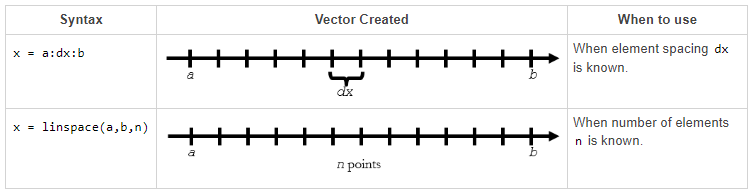

### Using The Colon Operator

The colon operator, `:`, is useful for when you know the desired spacing between elements of the vector. 

Here are some examples:

Creates a vector that starts at `1`, ends at `7`, and elements are separated by `2`.

`x` `=` `1``:``2``:``7`

`x` `=    `

`1`    `3`    `5`    `7`

To create a vector with spacing 1, you can omit the spacing value in the syntax. MATLAB will use a default spacing of `1`.

`x` `=` `1``:``4`

`x` `=    `

`1`    `2`    `3`    `4`

This creates a vector that starts at `1`, ends at `8`, and elements are separated by `3`.

If the end points are not separated by an integer number of spacings, the vector will be cut off at the element closest to, but not exceeding the end point.

`x` `=` `1``:``3``:``8`

`x` `= `

`1`  `4`  `7` 

### Using `linspace`

The `linspace` function is useful for when you want to guarantee that a vector has exactly `n` elements, and contains both the start and end points.

Here are some examples:

Creates a vector that starts at `1`, ends at `7`, and contains `5` elements.

`x` `=` `linspace``(``1``,``7``,``5``)`

`x` `=    `

`1.0000`    `2.5000`    `4.0000`    `5.5000`    `7.0000`

Creates a vector that starts at `-``pi`, ends at `pi`, and contains `4` elements.

`x` `=` `linspace``(``-``pi``,``pi``,``4``)`

`x` `=    `

`-3.1416`   `-1.0472`    `1.0472`    `3.1416`

If the number of elements is omitted, `linspace` defaults to creating a vector with 100 elements.

Create a row vector named `x` that starts at `5`, ends at `15`, and whose elements are separated by `1`.

x = 5:15;

Create a variable named `y` that contains the row vector shown below.

 `3`  `5`  `7`  `9`  `11`

y = 3:2:11;

Create a row vector named `z` that starts at `5`, ends at `1`, and whose elements are spaced by `-1.`

z = 5:-1:1;

Create a row vector named `A` that starts at `0`, ends at `12` and whose elements are spaced by `5`.

A = 0:5:12;

Create a row vector named `B` that starts at `0`, ends at `1` and contains `90` evenly-spaced elements.

B = linspace(0,1,90);

Create a row vector named `C` that starts at `3*pi`, ends at `-pi` and contains `20` evenly-spaced elements.

C = linspace(3*pi,-pi,20);

### Build Arrays From MATLAB Functions

MATLAB has a number of built-in functions that allow one to create arrays. The most commonly used functions are probably `zeros`, `ones`, and iterations of the `rand` function. Learn more about array creation functions by completing the tasks below.

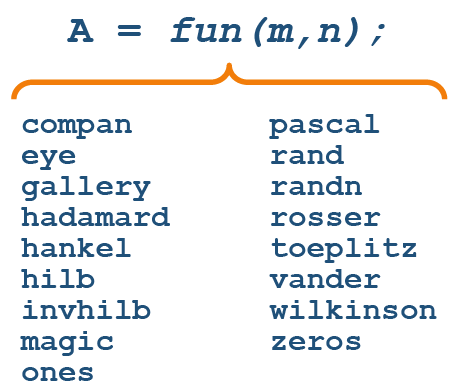

## TASK 1

Create an array named `x` that has `3` rows and `4` columns and where every element is the number `1`.

x = ones(3,4);

## TASK 2

Create an array named `x` that has `3` rows and `4` columns and where every element is the number `5`.

x = ones(3,4).*5;

## TASK 3

The [`rand`](https://www.mathworks.com/help/matlab/ref/rand.html) function creates a matrix of uniformly distributed random numbers. Random numbers can be useful for creating simulations.

Create a 100-by-1 vector of uniformly distributed random numbers with the name `xU`.

xU = rand(100,1);

## TASK 4

The [`randn`](https://www.mathworks.com/help/matlab/ref/randn.html) function creates a matrix of *normally* distributed random numbers.

Create a 100-by-1 vector of normally distributed random numbers with the name `xN`.

xN = randn(100,1);

## TASK 5

The [`randi`](https://www.mathworks.com/help/matlab/ref/randi.html) function creates a matrix of uniformly distributed random integers. Provide the maximum value as the first input, followed by the size of the array you want to create.

`v` `=` `randi``(``maxVal``,``m``,``n``)`

Create a 100-by-1 vector of uniformly distributed random integers with a maximum value of 10. Name the vector `xI`.

xI = randi(10,100,1);

## TASK 6

The uniformly distributed random integers generated by `randi` lie between one and the specified maximum value by default.

You can specify the interval over which the random integers are distributed using

`x` `=` `randi``([``minVal` `maxVal``]``,``m``,``n``)`

This code will generate random integers between `minVal` and `maxVal`

Use `randi` to create a 100-by-1 vector of uniformly distributed random integers between `11` and `20`. Name the vector `xI2.`

xI2 = randi([11,20],100,1);

## TASK 7

The uniformly distributed random numbers generated by `rand` lie between zero and one by default.

The `rand` function doesn't allow you to specify the interval over which the numbers are distributed.

If you want uniformly distributed numbers between values `a` and `b`, you can compute the following:

`x` `=` `a` `+` `(``b``-``a``)``*``rand``(``m``,``n``)`

Use `rand` to create a 100-by-1 vector of uniformly distributed random numbers between `-1` and `1`. Name the vector `xU2`

xU2 = -1 + (1 - (-1)) .* rand(100,1);

## TASK 8

Similarly, normally distributed random numbers generated by the `randn` function will have a mean of zero and a standard deviation of one by default.

If you want normally distributed numbers with mean `M` and standard deviation `sd`, you can compute the following:

`x` `=` `M` `+` `sd``*``randn``(``m``,``n``)`

Use `randn` to create a 100-by-1 vector of normally distributed random numbers with mean `100` and standard deviation `5`. Name the vector `xN2`.

xN2 = 5 .* randn(100,1) + 100;

## Combining Matrices

The bracket operators, `[ and ]`, are used to concatenate multiple matrices (or vectors) together. The more generic way to concatenate arrays is to use the `cat()` funcion (see `help cat`).

We can concatenate in the verical direction (the first dimension) by using the semi-colon (`;`) inside the brackets, between each element being operated on.

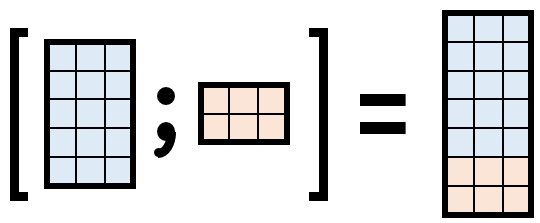

We can concatenate in the horizonal direction (the second dimension) by using either a space or a comma (`,`) inside the brackets, between each element being operated on.

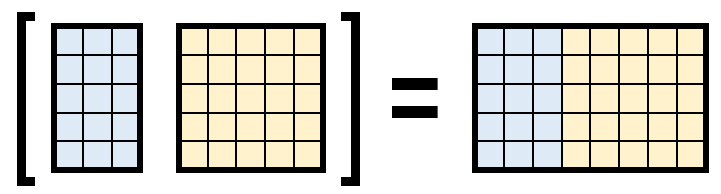

We can also combine arrays in multiple dimensions at once:

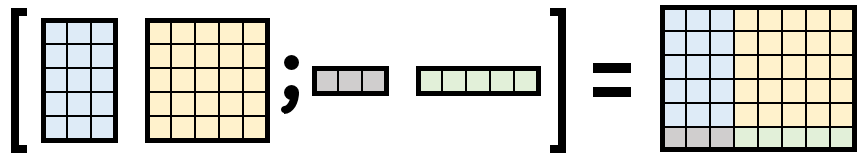

This operation can be thought of as a nested combination. For example, in the following code example, we show multiple concatenation operations.

array1 = [1,2,3;4,5,6];          % 2x3
array2 = [1,2,3,4;5,6,7,8] + 10; % 2x4
array3 = [1,2,3]+20;             % 1x3
array4 = [4,5,6,7]+20;           % 1x4

% Combine by columns on inner and by rows on outer
combinedArrays1 = [ ...
  [ array1, array2 ]; ...
  [ array3, array4 ] ...
  ]

combinedArrays1 =      1     2     3    11    12    13    14
     4     5     6    15    16    17    18
    21    22    23    24    25    26    27


% Combine by columns on inner and by rows on outer
combinedArrays2 = [ ...
  [ array1; array3 ], ...
  [ array2; array4 ] ...
  ]

combinedArrays2 =      1     2     3    11    12    13    14
     4     5     6    15    16    17    18
    21    22    23    24    25    26    27


% Verify both operations produced the same array:
isequal(combinedArrays1,combinedArrays2)

ans = logical
   1


% Advanced: Use if statement to produce Equal! or Not Equal! in the output.
if isequal(combinedArrays1,combinedArrays2), disp("Equal!"); else, disp("Not Equal!"); end

Equal!


Perform the following tasks to learn more about combining matrices.

Do not edit. This code defines the matrices.

A = [1 2 3;4 5 6]

A =      1     2     3
     4     5     6


B = [1 2;3 4;5 6]

B =      1     2
     3     4
     5     6


C = [1 2 3;4 NaN 6;7 8 9]

C =      1     2     3
     4   NaN     6
     7     8     9


## Task 1

You can concatenate two matrices horizontally (side-by-side) if they are the same height (have an equal number of rows).

Use square brackets around the matrices and separate them with a space.

`x` `=` `[``x``11` `;` `x``21``]``;`

`y` `=` `[``y``11` `y``12` `;` `y``21` `y``22``]``;`

`z` `=` `[``x` `y``]`

     `x``11` `y``11` `y``12`

     `x``21` `y``21` `y``22`

**TASK**

Create a 3-by-5 matrix named `BC` concatenating `B` and `C` where `B` is on the left and `C` is on the right.

BC = [B,C];

## Task 2

You can concatenate two matrices vertically (stacked on top of one another) using `;` if they are the same width (have an equal number of columns).

Use square brackets around the matrices and separate them with a `;`.

`x` `=` `[``x``11` `x``12``;` `x``21` `x``22``]``;`

`y` `=` `[``y``11` `y``12``]``;`

`z` `=` `[``x``;``y``]`

     `x``11` `x``12`

     `x``21` `x``22`

     `y``11` `y``12`

**TASK**

Create a 5-by-3 matrix named `CA` where `C` is on top of `A`.

CA = [C;A];

## Task 3

Add a row containing `10`, `11`, and `12`, in order, to the bottom of `C`. Name the resulting matrix `CR`.

  `1`   `2`   `3` 

  `4` `NaN`   `6` 

  `7`   `8`   `9` 

 `10`  `11`  `12`  

CR = [C;10,11,12];

## Task 4

Add a column containing `10`, `11`, and `12`, in order, to the right of `C`. Name the resulting matrix `CC`.

  `1`   `2`   `3`  `10` 

  `4` `NaN`   `6`  `11` 

  `7`   `8`   `9`  `12` 

CC = [C,[10;11;12]];

## Extracting Values From An Array

Every MATLAB array (scalars included) posses a method for subscripted referencing. In this document, we will only cover the subscripted referencing as it pertains to vectors and matrices, however the principals are identical for other array-like data types, such as cell and struct arrays, tables, and other object arrays.

The process of performing subscripted referencing is commonly referred to as "Indexing", and in other languages, e.g., Python, it is often referred to as "slicing", especially when the indexing operations extracts more than 1 item from the array.  In MATLAB there are 3 types of indexing, we will focus on the most broadly implemented type which works for arrays of all data types.

To index into an array, we can think of the array as a function and use parentheses after the array-containing variable name. Inside the parentheses, we can indicate which rows and columns we'd like to extract. *Note: if you're familiar with other languages, remember that MATLAB is a copy on write language, which means if we 'extract' values from an array we are simply making a copy of those values to memory and not removing them.

`A(:,n)`, `A(m,:)`, `A(:)`, and `A(j:k)` are common indexing expressions for a matrix `A` that contain a colon. When you use a colon as a subscript in an indexing expression, such as `A(:,n)`, it acts as shorthand to include *all* subscripts in a particular array dimension. It is also common to create a vector with a colon for the purposes of indexing, such as `A(j:k)`. Some indexing expressions combine both uses of the colon, as in `A(:,j:k)`.

Common indexing expressions that contain a colon are:

- `A(:,n)` is the `n`th column of matrix `A`.

- `A(m,:)` is the `m`th row of matrix `A`.

- `A(:,:,p)` is the `p`th page of three-dimensional array `A`.

- `A(:)` reshapes all elements of `A` into a single column vector. This has no effect if `A` is already a column vector.

- `A(:,:)` reshapes all elements of `A` into a two-dimensional matrix. This has no effect if `A` is already a matrix or vector.

- `A(j:k)` uses the vector `j:k` to index into `A` and is therefore equivalent to the vector `[A(j), A(j+1), ..., A(k)]`.

- `A(:,j:k)` includes all subscripts in the first dimension but uses the vector `j:k` to index in the second dimension. This returns a matrix with columns `[A(:,j), A(:,j+1), ..., A(:,k)]`.

Let's use the variables defined in the previous section called, `A`, `B`, and `C`.

## Task 1

`A(I)` is an array formed from the elements of `A` specified by the subscript vector `I`. The resulting array is the same size as `I` except for the special case where `A` and `I` are both vectors. In this case, `A(I)` has the same number of elements as `I` but has the orientation of `A`.

 Extract the first element of the matrix `A` and store it in a variable named `a1`.

a1 = A(1);

## Task 2

`A(I,J)` is an array formed from the elements of the rectangular submatrix of `A`, specified by the subscript vectors `I` and `J`. The resulting array has `length(I)` rows and `length(J)` columns. A colon used as a subscript indicates all elements in that dimension. For example, `A(I,:)` means all columns of those rows specified by vector `I`. Similarly, `A(:,J)` means all rows of columns specified by `J`.

Extract the value from the second row and second column of `A` and store the value in a variable named `a22`.

a22 = A(2,2);

## Task 3

MATLAB stores all arrays as vectors. This means there is a linear organization of any array and the pattern is such that the index is from 1 to the total number of elements in the array, organized first by rows, then by columns, then by pages (3rd dimension), and so forth. The pattern is as such for a matrix:

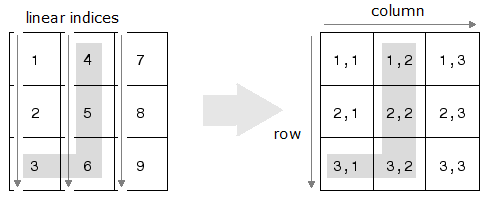

This means that we can access any element in the matrxi using a single, *linear index.* This is useful when we want to extract individual elements from an array that are not contiguous. Let's assume we need to extract 2 values from our matrix `A`, that are located in the (2,1) and (1,3) positions. We might set up two vectors to indicate the rows and columns we want.

% Do not edit
row = [2,1];
col = [1,3];

If we simply use these indices in our matrix indexing we get the following:

A(row,col)

ans =      4     6
     1     3


Clearly, we did not get 2 values, but instead we got a 2x2 matrix, a submatrix of A at the intersection of the row and column indices. The two values we are after are `[4,3]`, in that order. Given the pattern above, we can use the following equation to convert between subscripted index to linear index:


$$I_{\mathrm{linear}}=N_{\mathrm{rows}}(I_{\mathrm{col}}-1)+I_{\mathrm{row}}$$


Where $I_{\mathrm{linear}}$ is the linear index given the number of rows in the matrix, $N_{\mathrm{rows}}$, and the subscripted indices of the columns, $I_{\mathrm{col}}$, and rows, $I_{\mathrm{row}}$.

Extract the values from A using linear indexing from the specified row and column subscripted indices in `row` and `col`. First, create a variable called `idx` that stores the linear indices as computed by your own implementation of the equation above. Then create a vector `aLinear` that contains the extracted values.

% HINT: calculate the number of rows of a matrix using the size() function
Nrows = size(A,1); % Do not edit (freebie)
idx = Nrows * (col - 1) + row;
aLinear = A(idx)

aLinear =      4     3


Note: MATLAB has a builtin function to acheive this. The syntax is: `idx = sub2ind(size(A),row,col);`

## Task 4

*Logical indexing. *There is one more type of indexing that can be used to extract values from an array. Although referred to as logical indexing, the better name for it would be conditional indexing because it is typically used to extract values that meet some condition or criteria. 

Consider the matrix `C` from above. The 3x3 matrix contains a `NaN` (not a number) value in the `(2,2)` index, i.e., the linear index `5`. Let's say we wanted to replace the `NaN` with the number 100. We can use the `isnan()` function to find the logical mask of the matrix that meet the criteria of being a `NaN`. Create a logical matrix using the `isnan()` function with the matrix `C` and store it in a variable called `nanIdx`.

nanIdx = isnan(C);

## Task 5

Logical arrays are useful for quickly creating, modifying, indexing arrays. In this task, we will use the logical array we created in the previous task to replace the `NaN` in a copy of the matrix `C`. To start, create a copy of matrix `C` into a variable named `CCopy`. Then use `nanIdx` to replace the `NaN` in `CCopy` with the number 100. The result should look like:

  `1`   `2`   `3`

  `4``  100  ``6`

  `7`   `8`   `9`

CCopy = C;
CCopy(nanIdx) = 100

CCopy =      1     2     3
     4   100     6
     7     8     9


`Hint: A copy can be made by simply using B = A;. Any changes to B will not result in changes to A (generally speaking).`

`Hint: The values indexed can be set to a new value by using the equals operator such that: V(idx) = U; where U is scalar.`

## Task 6

Indexing may also be achieved by using vectors. Sometimes it is useful to gather many rows of a column or columns. Using the subscripted indexing approach, we can collect multiple indices using the colon (`:`) operator. If you want all the indices in particular dimension, you can simply use the colon `:` operator without any start and end points specified. For example, to get all the values of a vector `Q`, we can simply use `Q(:)` and we will just create a column vector of all the values in `Q`. To gather certain rows we can use the special keyword `end` as the end point. For example, to gather all the rows after the 2nd row of the first two columns in a matrix `Z`, we can use: `Z(3:end,[1,2])`. 

Using these principals, create a matrix named `D` that contains elements of C as follows: `D` must contain all rows of `C,` except the first row, from the first and last columns.

D = C(2:end,[1,end])

D =      4     6
     7     9
